%==========================================================================
% Author:    Naghmeh Akhavan, PhD (N. Akhavan)
% Affil.:    University of Michigan
% Contact:   nakhavan@umich.edu
%
% Purpose:
%   Fit a 2-component Gaussian mixture model (GMM) to z = log(|N|) where
%   |N| = NREM duration (seconds) for rodent datasets (Mouse/Rat; Light/Dark),
%   using a consistent long-wake (LW) drop rule and fixed REMpre bin edges.
%
% What this script does (per dataset):
%   1) Read a per-cycle "BigResultTable_*" CSV.
%   2) Normalize key numeric columns (REMpre, NREM, IREM, Wake, Movement).
%      If IREM is missing, reconstruct IREM = NREM + Wake + Movement.
%   3) Long-wake filtering (in-place):
%        - Prefer MaxWake* columns (seconds) as a proxy for max contiguous
%          Wake block within IREM.
%      Drop a cycle if chosen Wake proxy >= WAKE_BREAK_MIN minutes.
%   4) Keep only cycles valid for the GMM:
%        NREM finite and > 0, REMpre finite and >= 0.
%   5) Add small uniform "jitter" to NREM (seconds) to reduce discretization
%      artifacts (epoch-quantization "combs"), then fit GMM on z = log(NREM_sec).
%   6) Plot:
%        - Lumped (all valid cycles) histogram + mixture and components
%        - Per fixed REMpre bins (seconds): same plots per bin
%          Bins: [0,30), [30,60), [60,90), [90,120), [120,150), [150,Inf)
%
% Statistics/implementation:
%   - Toolbox-free EM algorithm (multiple random starts; bounded SD).
%   - Histogram binning uses Scott's rule in log-space.
%   - Optional "tail-bin merge" if last bin has too few samples.
%
% Outputs:
%   - Figures displayed; optionally saved next to each CSV if SAVE_FIGS = true.
%   - Console summary per dataset: Total/Kept/Dropped and fitted parameters.
%
% Last updated: 2026-01-16
%==========================================================================


clear; clc; close all;


## Long-wake threshold

WAKE_BREAK_MIN = 2;                  % minutes
WAKE_BREAK_SEC = WAKE_BREAK_MIN*60;  % seconds


## Paths

mouseLightCSV = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse light data-Naghmeh\BigResultTable_mouse_light.csv";
mouseDarkCSV  = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse dark data-Naghmeh\BigResultTable_mouse_dark.csv";
ratLightCSV   = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat light data-Naghmeh\BigResultTable_rat_light.csv";
ratDarkCSV    = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat dark data-Naghmeh\BigResultTable_rat_dark.csv";


## Knobs

SAVE_FIGS      = false;
SHOW_WEIGHTED  = true;    % show w_k*N(mu,sd)
SHOW_SHAPES    = false;   % show normalized shapes
sdMinLog       = 0.04;
sdMaxLog       = 4.0;
nStarts        = 25;
JITTER_FRAC    = 0.25;    % ≤ 1/4 epoch de-quantization

% small-n behavior
MIN_N_FOR_GMM  = 15;      
VAR_GUARD      = 2*sdMinLog;
MERGE_TAIL_IF_SMALL = true;

% Colors
mouseCol = [0.55 0.27 0.68];
ratCol   = [0.90 0.50 0.10];


## Species config (epoch only used for jitter size)

CFG.Mouse.epoch = 2.5;  CFG.Mouse.col = mouseCol;
CFG.Rat.epoch   = 4.0;  CFG.Rat.col   = ratCol;


## FIXED REMpre edges (seconds) — 6 bins -> 7 edges

REM_EDGES_SEC = [0 30 60 90 120 150 inf];


## Run all four datasets

Mouse (Light) — Total=5300 | Kept=4005 | Dropped=1295  [LW-only=1283; Wake (total in IREM; fallback proxy) >= 120s; thr=2 min]


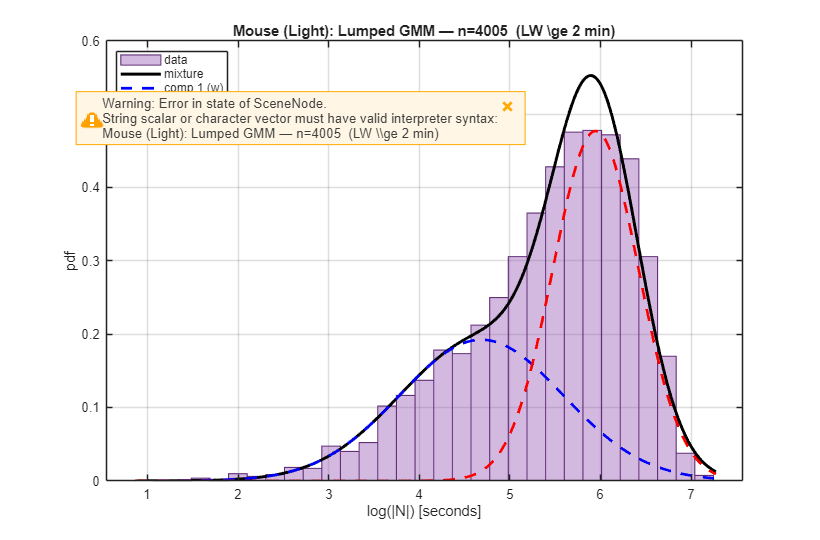

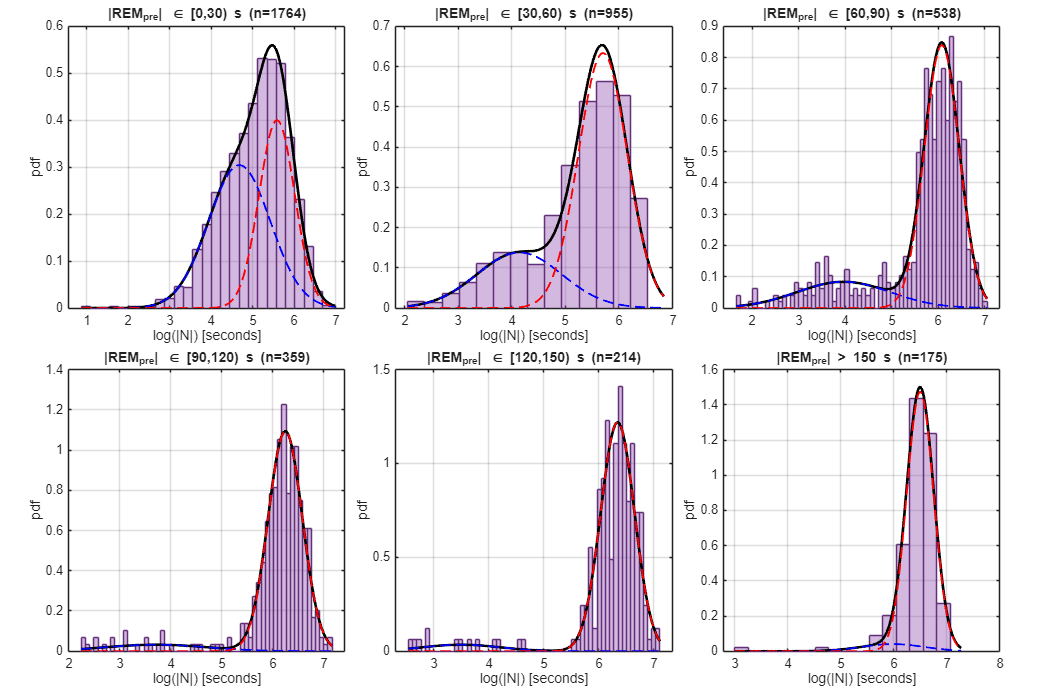

Mouse (Light) lumped: w=[0.435 0.565], mu=[4.686 5.947], sd=[0.903 0.472], n=4005  (LW\ge2min)


run_one(mouseLightCSV, "Mouse", "Light", CFG.Mouse, REM_EDGES_SEC, ...
        SAVE_FIGS, SHOW_WEIGHTED, SHOW_SHAPES, sdMinLog, sdMaxLog, nStarts, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, MIN_N_FOR_GMM, VAR_GUARD, MERGE_TAIL_IF_SMALL);

Mouse (Dark) — Total=1307 | Kept=739 | Dropped=568  [LW-only=564; Wake (total in IREM; fallback proxy) >= 120s; thr=2 min]


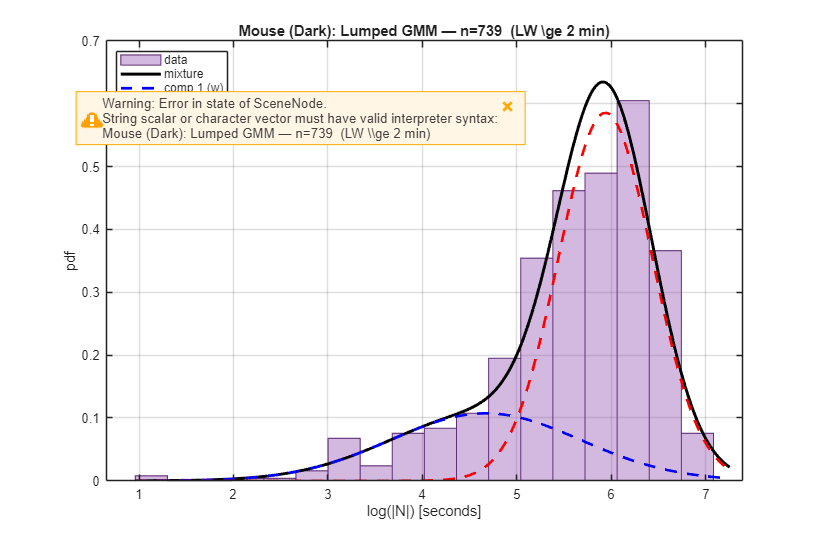

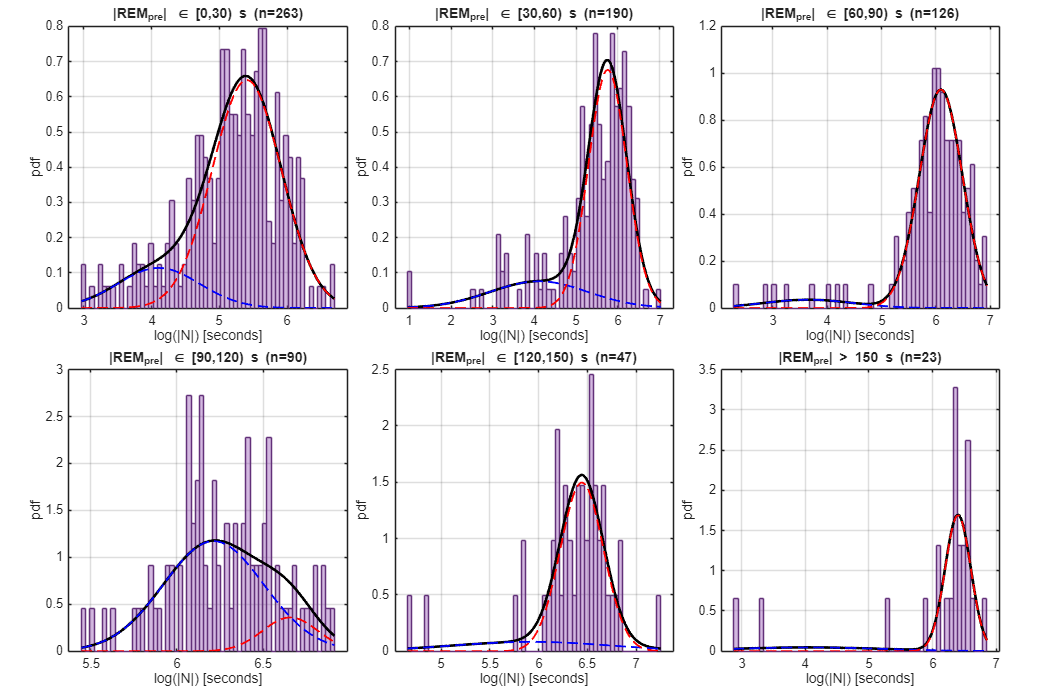

Mouse (Dark) lumped: w=[0.270 0.730], mu=[4.670 5.938], sd=[1.005 0.497], n=739  (LW\ge2min)



run_one(mouseDarkCSV,  "Mouse", "Dark",  CFG.Mouse, REM_EDGES_SEC, ...
        SAVE_FIGS, SHOW_WEIGHTED, SHOW_SHAPES, sdMinLog, sdMaxLog, nStarts, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, MIN_N_FOR_GMM, VAR_GUARD, MERGE_TAIL_IF_SMALL);

Rat (Light) — Total=2766 | Kept=2089 | Dropped=677  [LW-only=674; Wake (total in IREM; fallback proxy) >= 120s; thr=2 min]


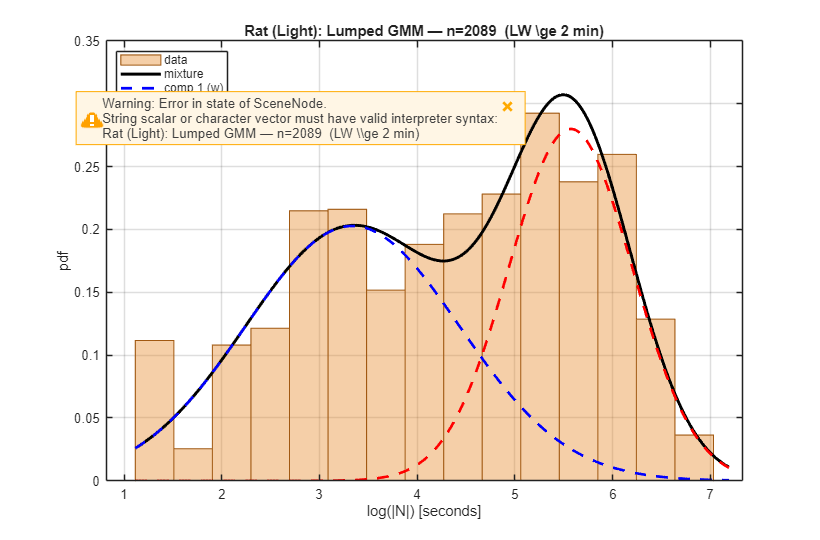

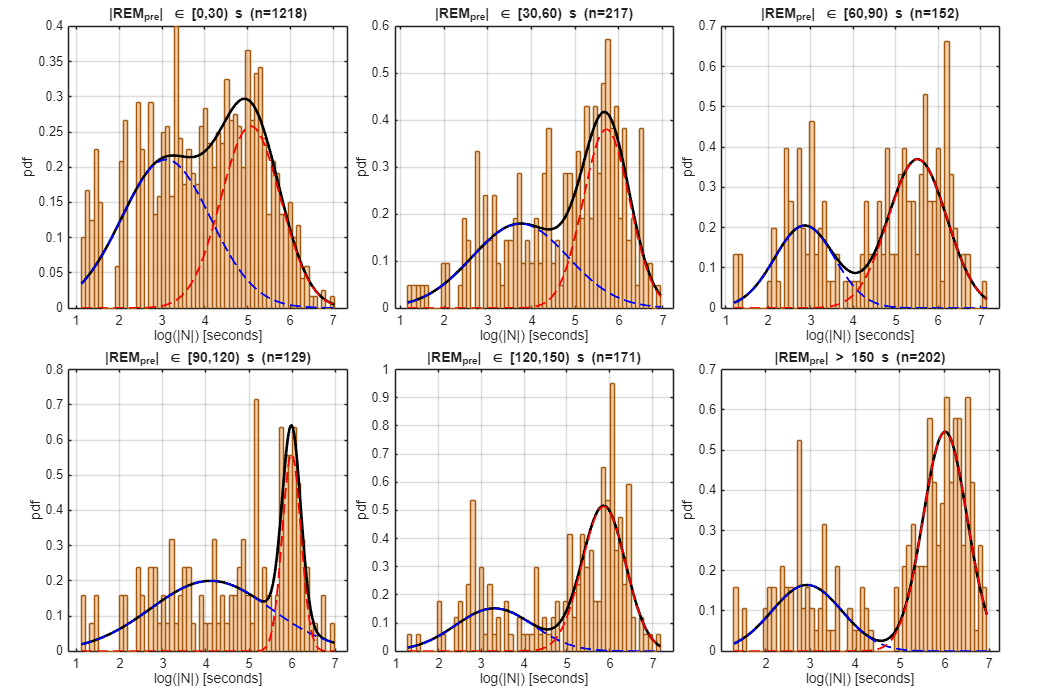

Rat (Light) lumped: w=[0.557 0.443], mu=[3.338 5.570], sd=[1.096 0.632], n=2089  (LW\ge2min)



run_one(ratLightCSV,   "Rat",   "Light", CFG.Rat,   REM_EDGES_SEC, ...
        SAVE_FIGS, SHOW_WEIGHTED, SHOW_SHAPES, sdMinLog, sdMaxLog, nStarts, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, MIN_N_FOR_GMM, VAR_GUARD, MERGE_TAIL_IF_SMALL);

Rat (Dark) — Total=2312 | Kept=1745 | Dropped=567  [LW-only=565; Wake (total in IREM; fallback proxy) >= 120s; thr=2 min]


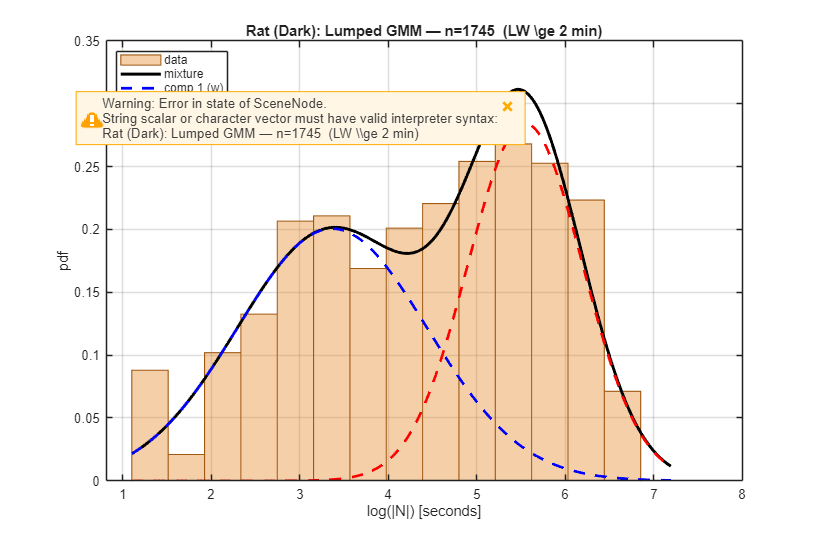

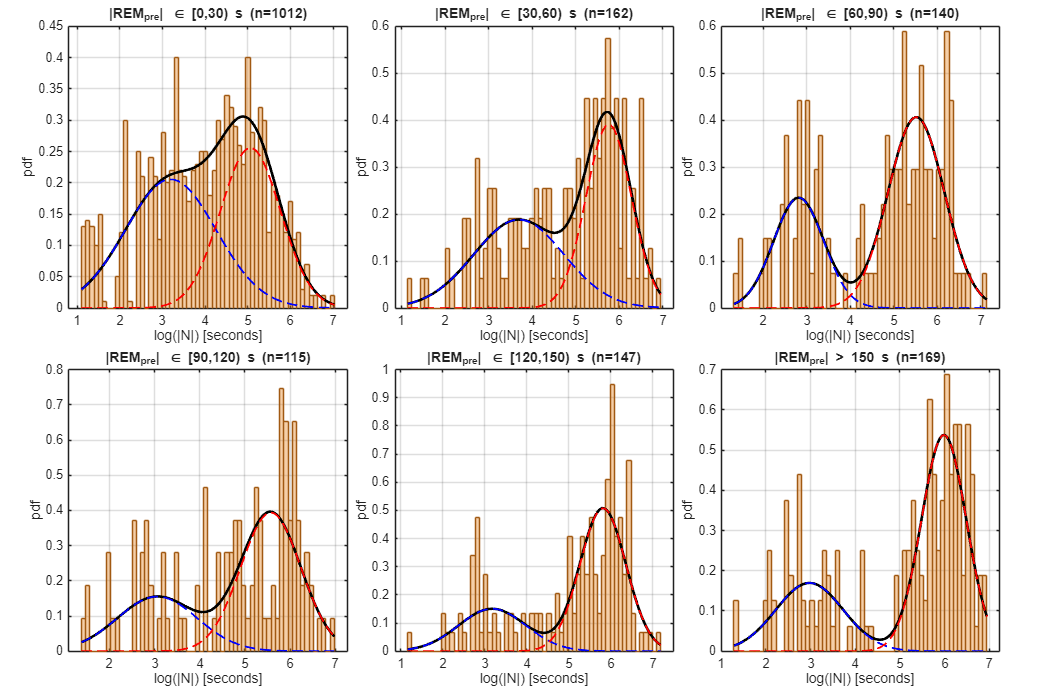

Rat (Dark) lumped: w=[0.539 0.461], mu=[3.366 5.547], sd=[1.072 0.648], n=1745  (LW\ge2min)



run_one(ratDarkCSV,    "Rat",   "Dark",  CFG.Rat,   REM_EDGES_SEC, ...
        SAVE_FIGS, SHOW_WEIGHTED, SHOW_SHAPES, sdMinLog, sdMaxLog, nStarts, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, MIN_N_FOR_GMM, VAR_GUARD, MERGE_TAIL_IF_SMALL);


fprintf("Done.\n");

Done.


## Function

function run_one(csvFile, species, phase, cfg, REM_EDGES_SEC, ...
                 SAVE_FIGS, SHOW_WEIGHTED, SHOW_SHAPES, sdMinLog, sdMaxLog, nStarts, JITTER_FRAC, ...
                 WAKE_BREAK_SEC, WAKE_BREAK_MIN, MIN_N_FOR_GMM, VAR_GUARD, MERGE_TAIL_IF_SMALL)

    assert(isfile(csvFile), 'CSV not found: %s', csvFile);
    Traw = readtable(csvFile, 'TextType','string');

    % Normalize columns (guarantee Wake exists + numeric)
    T = normalize_cycles_csv(Traw);

    % Long-wake filtering (CONSISTENT with pooled-stats script)
    [dropFlagLW, filterMsg] = longwake_dropflag(T, WAKE_BREAK_SEC);

    totalAll = height(T);
    Tlw      = T(~dropFlagLW, :);
    droppedLW = nnz(dropFlagLW);

    % Validity (match GMM usage: NREM finite & >0)
    valid = isfinite(Tlw.NREM) & (Tlw.NREM > 0) & isfinite(Tlw.REMpre) & (Tlw.REMpre >= 0);
    Tuse  = Tlw(valid,:);

    kept    = height(Tuse);
    dropped = totalAll - kept;  % LW + invalid NREM/REMpre
    fprintf('%s (%s) — Total=%d | Kept=%d | Dropped=%d  [LW-only=%d; %s; thr=%g min]\n', ...
            species, phase, totalAll, kept, dropped, droppedLW, filterMsg, WAKE_BREAK_MIN);

    % Use REMpre (seconds) for *binning*; |N| = NREM seconds for fitting
    RP_sec = double(Tuse.REMpre(:));
    N_sec  = double(Tuse.NREM(:));

    if numel(N_sec) < 30
        warning('%s (%s): not enough valid cycles after filtering (n=%d).', species, phase, numel(N_sec));
        return;
    end

    % Small jitter to fight discretization "combs"
    if JITTER_FRAC > 0
        jitter = (rand(numel(N_sec),1)-0.5) * (2*JITTER_FRAC*cfg.epoch);
        N_sec  = max(N_sec + jitter, eps);
    end

    z = log(N_sec);  % ln seconds for the GMM

    % EM options (no quantiles)
    opts = struct('nStarts',nStarts,'maxIter',300,'tol',1e-6, ...
                  'trimFrac',0.0,'sdMin',sdMinLog,'sdMax',sdMaxLog);


## Lumped fit (all valid cycles)

   % fit the 2-comp GMM
    [wL, muL, sdL, infoL] = fit_gmm_1d_noquant(z, 2, opts);
   % Histogram bin + mixture pdf on a grid 
    [edgesLog, xx] = scott_bins(z);
    mix = gmm_pdf_grid(xx, wL, muL, sdL);
   % plot lumped histogram + mixture
    f1 = figure('Color','w','Position',[120 120 820 540], ...
        'Name', sprintf('%s (%s): Lumped GMM (log-seconds)', species, phase));
    histogram(z, edgesLog, 'Normalization','pdf', ...
        'FaceColor', cfg.col, 'FaceAlpha',0.38, 'EdgeColor', cfg.col*0.7, 'LineWidth',0.8);
    hold on; grid on; box on;
    plot(xx, mix, 'k-', 'LineWidth',2.2);
    if SHOW_WEIGHTED
        plot(xx, wL(1)*gauss_pdf(xx,muL(1),sdL(1)), 'b--', 'LineWidth',2.0);
        plot(xx, wL(2)*gauss_pdf(xx,muL(2),sdL(2)), 'r--', 'LineWidth',2.0);
    end
    if SHOW_SHAPES
        peak = max(mix);
        c1 = gauss_pdf(xx,muL(1),sdL(1)); c1 = c1/max(c1)*peak;
        c2 = gauss_pdf(xx,muL(2),sdL(2)); c2 = c2/max(c2)*peak;
        plot(xx, c1, 'b-.', 'LineWidth',1.6);
        plot(xx, c2, 'r-.', 'LineWidth',1.6);
    end
    xlabel('log(|N|) [seconds]'); ylabel('pdf');
    title(sprintf('%s (%s): Lumped GMM — n=%d  (LW \\ge %g min)', ...
          species, phase, numel(z), WAKE_BREAK_MIN));
    legend(makeLegend(SHOW_WEIGHTED, SHOW_SHAPES), 'Location','northwest');

    if SAVE_FIGS
        [pdir, base] = fileparts(csvFile);
        exportgraphics(f1, fullfile(pdir,[base sprintf('_gmm_lumped_lnsec_LW%gmin.png', WAKE_BREAK_MIN)]), 'Resolution', 220);
    end


## Per-REMpre fixed bins (seconds)

% assign each cycle to a REMpre bin
    binID = discretize(RP_sec, REM_EDGES_SEC);
    nBins = numel(REM_EDGES_SEC)-1;

    [r,c] = layout_for_bins(nBins);  % 6 -> 2x3
    f2 = figure('Color','w','Position',[100 100 1100 720], ...
        'Name', sprintf('%s (%s): GMM per fixed REM_{pre} bins', species, phase));
    tiledlayout(r, c, 'TileSpacing','compact','Padding','compact');
% loop through these bins
    for b = 1:nBins
        zb = z(binID==b);
        mergedNote = '';
        if MERGE_TAIL_IF_SMALL && (numel(zb) < MIN_N_FOR_GMM) && (b == nBins)
            zb = z(binID >= b-1);   % merge last two bins
            mergedNote = ' (merged tail bins)';
        end

        nexttile; hold on; grid on; box on;
        [edgesB, xxB] = scott_bins(zb);
        histogram(zb, edgesB, 'Normalization','pdf', ...
                  'FaceColor', cfg.col, 'FaceAlpha',0.38, 'EdgeColor', cfg.col*0.7);
% Fit GMM per bin (for enough data + enough variance)
        didMixture = false;
        if numel(zb) >= MIN_N_FOR_GMM && std(zb,'omitnan') > VAR_GUARD
            try
                [wB, muB, sdB] = fit_gmm_1d_noquant(zb, 2, opts);
                mixB = gmm_pdf_grid(xxB, wB, muB, sdB);
                plot(xxB, mixB, 'k-', 'LineWidth',2.0);
                if SHOW_WEIGHTED
                    plot(xxB, wB(1)*gauss_pdf(xxB,muB(1),sdB(1)), 'b--', 'LineWidth',1.4);
                    plot(xxB, wB(2)*gauss_pdf(xxB,muB(2),sdB(2)), 'r--', 'LineWidth',1.4);
                end
                didMixture = true;
            catch
                didMixture = false;
            end
        end
% check for fallback
        if ~didMixture && numel(zb) >= 3 && std(zb,'omitnan')>0
            mu1 = mean(zb,'omitnan'); sd1 = std(zb,'omitnan');
            plot(xxB, gauss_pdf(xxB,mu1,sd1), 'k--', 'LineWidth',1.6);
        end
% bin title label
        xlabel('log(|N|) [seconds]'); ylabel('pdf');
        lo = REM_EDGES_SEC(b); hi = REM_EDGES_SEC(b+1);
        if isinf(hi)
            ttl_edge = sprintf('|REM_{pre}| > %d s', lo);
        else
            ttl_edge = sprintf('|REM_{pre}| \\in [%d,%d) s', lo, hi);
        end
        title(sprintf('%s (n=%d)%s', ttl_edge, numel(zb), mergedNote));
    end
% save per bin figure
    if SAVE_FIGS
        [pdir, base] = fileparts(csvFile);
        exportgraphics(f2, fullfile(pdir,[base sprintf('_gmm_bins_fixed_lnsec_LW%gmin.png', WAKE_BREAK_MIN)]), 'Resolution', 220);
    end
% print fitted lumped params to console
    fprintf('%s (%s) lumped: w=[%.3f %.3f], mu=[%.3f %.3f], sd=[%.3f %.3f], n=%d  (LW\\ge%gmin)\n', ...
        species, phase, wL(1),wL(2), muL(1),muL(2), sdL(1),sdL(2), infoL.n, WAKE_BREAK_MIN);
end


## Functions

% normalize_cycles_cvs(T): ensures numeric columns exists and are doubles
% (rempre, NREM, IREM, Wake, Movement)
% longwake_dropflag: chooses a column for wake-based dropping
% scott_bins(z): compute histogram edges using scott's rule bandwidth
% fit_gmm_1d_noquant: EM for 1D GMM without quantile clipping
% em_core(): the actual EM loop
% gmm_pdf_grid, gauss_pdf: Evaluate mixture pdf and Gaussian pdf
% layout_for_bins(n): choose a good tiled layout for n bins (here 6 -> 2*3)
function T = normalize_cycles_csv(T)
    % Ensure required numeric columns exist and are numeric.
    need = ["REMpre","NREM","IREM","Wake","Movement"];
    vn = string(T.Properties.VariableNames);

    for v = need
        if ~ismember(v, vn)
            T.(v) = NaN(height(T),1);
        end
        T.(v) = double(T.(v));
    end

    % Reconstruct IREM if missing or all-NaN and components exist
    if (~ismember("IREM", vn)) || all(isnan(T.IREM))
        if all(ismember(["NREM","Wake","Movement"], string(T.Properties.VariableNames)))
            T.IREM = double(T.NREM) + double(T.Wake) + double(T.Movement);
        end
    end
end

%% ================= Long-wake dropflag (consistent) =================
function [dropFlag, msg] = longwake_dropflag(T, WAKE_BREAK_SEC)
    vn = string(T.Properties.VariableNames);

    maxWakeCandidates = ["MaxWakeSec","MaxWake_s","MaxWakeInIREMSec","MaxWakeInIREM_s", ...
                         "MaxWakeBlockSec","MaxWakeBlock_s"];

    idx = find(ismember(maxWakeCandidates, vn), 1);
    if ~isempty(idx)
        cname = maxWakeCandidates(idx);
        maxWakeSec = double(T.(cname));
        dropFlag = isfinite(maxWakeSec) & (maxWakeSec >= WAKE_BREAK_SEC);
        msg = sprintf("max Wake block via %s >= %gs", cname, WAKE_BREAK_SEC);
        return;
    end

    % Fallback: total Wake in IREM
    if ismember("Wake", vn)
        w = double(T.Wake);
        dropFlag = isfinite(w) & (w >= WAKE_BREAK_SEC);
        msg = sprintf("Wake (total in IREM; fallback proxy) >= %gs", WAKE_BREAK_SEC);
        return;
    end

    % No info => no filtering
    dropFlag = false(height(T),1);
    msg = "NO long-wake column found (no MaxWake*/Wake) — no filtering applied";
end

%% ================= helpers =================
function [edges, xx] = scott_bins(z)
    z = z(:); z = z(isfinite(z));
    n = numel(z);
    if n < 2 || std(z)==0
        edges = linspace(min(z), max(z), 15);
        xx = linspace(min(z), max(z), 400);
        return;
    end
    bw = 3.5*std(z) / max(n^(1/3), eps);
    zmin = min(z); zmax = max(z);
    if ~isfinite(bw) || bw<=0
        nb = 60; edges = linspace(zmin, zmax, nb+1);
    else
        edges = zmin:bw:zmax;
        if numel(edges) < 15, edges = linspace(zmin, zmax, 60+1); end
    end
    xx = linspace(zmin, zmax, 400);
end

function [w, mu, sd, info] = fit_gmm_1d_noquant(x, K, opts)
    x = x(:); x = x(isfinite(x));
    g = @(f,d) (isfield(opts,f)&&~isempty(opts.(f))) * opts.(f) + (~isfield(opts,f)||isempty(opts.(f))) * d;
    nStarts  = g('nStarts',20); maxIter = g('maxIter',300); tol = g('tol',1e-6);
    trimFrac = g('trimFrac',0.0); sdMin = g('sdMin',0.04); sdMax = g('sdMax',4.0);

    muX = mean(x); sdX = std(x);
    if isfinite(sdX) && sdX>0
        lo = muX - 6*sdX; hi = muX + 6*sdX;
        x = x(x>=lo & x<=hi);
    end
    n = numel(x);

    log2pi = log(2*pi); bestLL = -inf; best = [];
    base_mu = muX + 0.5*sdX*linspace(-1,1,K);
    base_sd = max(sdMin, 0.3*sdX)*ones(1,K);
    base_w  = ones(1,K)/K;

    for s=1:nStarts
        mu0 = base_mu + 0.10*sdX*randn(1,K);
        sd0 = max(sdMin, min(sdMax, base_sd));
        w0  = base_w;
        [w1, mu1, sd1, LL] = em_core(x, w0, mu0, sd0, maxIter, tol, trimFrac, sdMin, sdMax, log2pi);
        if LL(end) > bestLL, bestLL = LL(end); best = {w1,mu1,sd1,LL}; end
    end
    [w, mu, sd, LL] = best{:}; info = struct('loglik',LL,'n',n,'nStarts',nStarts);
end

function [w, mu, sd, LL] = em_core(x, w, mu, sd, maxIter, tol, trimFrac, sdMin, sdMax, log2pi)
    n = numel(x); K = numel(w); LL = zeros(maxIter,1); trimN = floor(trimFrac*n);
    for it=1:maxIter
        logp = zeros(n,K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (x-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2); P = exp(logp - m); s = sum(P,2); gamma = P ./ max(s,eps);

        if trimN>0
            [~,idx]=sort(s,'ascend'); keep=true(n,1); keep(idx(1:trimN))=false;
        else
            keep=true(n,1);
        end

        Nk = sum(gamma(keep,:),1);
        w  = Nk ./ max(sum(Nk),eps); w = max(w,1e-4); w = w/sum(w);
        for k=1:K
            mu(k) = sum(gamma(keep,k).*x(keep)) / max(Nk(k),eps);
            v     = sum(gamma(keep,k).*(x(keep)-mu(k)).^2) / max(Nk(k),eps);
            sd(k) = sqrt(max(sdMin^2, min(v, sdMax^2)));
        end

        xk = x(keep);
        logp = zeros(sum(keep),K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (xk-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2); LL(it) = sum(m + log(sum(exp(logp - m),2)));
        if it>1 && abs(LL(it)-LL(it-1)) < tol*max(1,abs(LL(it-1)))
            LL = LL(1:it); break;
        end
    end
    LL = LL(1:it);
end

function y = gmm_pdf_grid(x, w, mu, sd)
    y = zeros(size(x));
    for k=1:numel(w), y = y + w(k)*gauss_pdf(x, mu(k), sd(k)); end
end

function y = gauss_pdf(x, m, s)
    y = (1./(s*sqrt(2*pi))) .* exp(-0.5*((x-m)./s).^2);
end

function L = makeLegend(showW, showS)
    L = {'data','mixture'};
    if showW, L = [L, {'comp 1 (w)','comp 2 (w)'}]; end
    if showS, L = [L, {'comp 1 (shape)','comp 2 (shape)'}]; end
end

function [r,c] = layout_for_bins(n)
    switch n
        case 1,  r=1; c=1;
        case 2,  r=1; c=2;
        case {3,4},  r=2; c=2;
        case 5,  r=2; c=3;
        case 6,  r=2; c=3;
        otherwise, c = ceil(sqrt(n)); r = ceil(n/c);
    end
end

